# This code is for filtering the data with random trigger and plotting the PIPICO


%% import the data if already converted to ANA
dir= 'E:\PhD\Adamantane_data\data\Ada_PEPICO_hv350eV_ke260_0003\Ada_PEPICO_hv350eV_ke260_0003_ana';
raw_data = IO.import_raw(dir);
addpath(genpath('E:\PhD\Adamantane_data\mdata'))
mdata = md_all();
data            = macro.filter(raw_data, mdata); %define the multiplicity of events
data_corrected = macro.correct(data, mdata);

Log: Detector image translation correction performed on det1
Log: Detector image rotation correction performed on det1
Log: Radial angle-dependent correction performed on det1
Log: Detector image translation correction performed on det2
Log: Detector image rotation correction performed on det2
Log: delta TOF correction performed on det2


data_converted = macro.convert(data_corrected, mdata);

Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2
Log: Background signal created for det2 on the signal(s) TOF,


## Event statistics from all data

e_TRG= macro.filter.write_coincidence_condition(1, 'det1'); % electron trigger
RND_TRG= macro.filter.write_coincidence_condition(0, 'det1'); % rnd trigger

[e_filter_et, ~]	= macro.filter.conditions_2_filter(data_converted,e_TRG);
data_stats.N_e = sum(e_filter_et);
[e_filter_rt, ~]	= macro.filter.conditions_2_filter(data_converted, RND_TRG);
data_stats.N_RND = sum(e_filter_rt);

%probability to detect j ions after electron trigger
y1=[];
for j =0:4
    etN =struct();
    etN.e_TRG= macro.filter.write_coincidence_condition(1, 'det1'); %electron trigger
    etN.ions= macro.filter.write_coincidence_condition(j, 'det2');
    [e_filter_etN, ~]	= macro.filter.conditions_2_filter(data_converted,etN);
    strg = ['etP_',num2str(j)];
    data_stats.(strg) = sum(e_filter_etN)/data_stats.N_e;
    y1 = [y1; data_stats.(strg) ];
end

%probability to detect j ions after RND trigger
y2=[];
for j =0:4
    rtN =struct();
    rtN.RND_TRG= macro.filter.write_coincidence_condition(0, 'det1'); %RND trigger
    rtN.ions= macro.filter.write_coincidence_condition(j, 'det2');
    [e_filter_rtN, ~]	= macro.filter.conditions_2_filter(data_converted,rtN);
    strg = ['rtP_',num2str(j)];
    data_stats.(strg) = sum(e_filter_rtN)/data_stats.N_RND;
    y2 = [y2; data_stats.(strg) ];
    
end

## TP

TP_0 = max(data_stats.etP_0 / data_stats.rtP_0,0) ;
TP_1 = max((data_stats.etP_1 - data_stats.rtP_1*TP_0) / data_stats.rtP_0,0);
TP_2 = max((data_stats.etP_2 - data_stats.rtP_2*TP_0 - data_stats.rtP_1*TP_1) / data_stats.rtP_0,0);
TP_3 = max((data_stats.etP_3 - data_stats.rtP_3*TP_0 - data_stats.rtP_2*TP_1 - data_stats.rtP_1*TP_2) ...
        / data_stats.rtP_0,0);
TP_4 = max((data_stats.etP_4 - data_stats.rtP_4*TP_0 - data_stats.rtP_3*TP_1 - data_stats.rtP_2*TP_2 - data_stats.rtP_1*TP_3) ...
        / data_stats.rtP_0,0);
    

## Pj

PD = 0.4; PD_bar = 1-PD;
P4 = max(TP_4 / PD^4,0);
P3 = max((TP_3 - 4*P4*PD_bar*PD^3)/PD^3,0);
P2 = max((TP_2 - 3*P3*PD_bar*PD^2 - 6*P4*PD_bar^2*PD^2)/PD^2,0);
P1 = max((TP_1 - 2*P2*PD_bar*PD - 3*P3*PD_bar^2*PD - 4*P4*PD_bar^3*PD)/PD,0);
P0 = max((TP_0 - P1*PD_bar - P2*PD_bar^2 - P3*PD_bar^3 - P4*PD_bar^4),0);

SC = data_stats.N_e / data_stats.N_RND;

## Hist

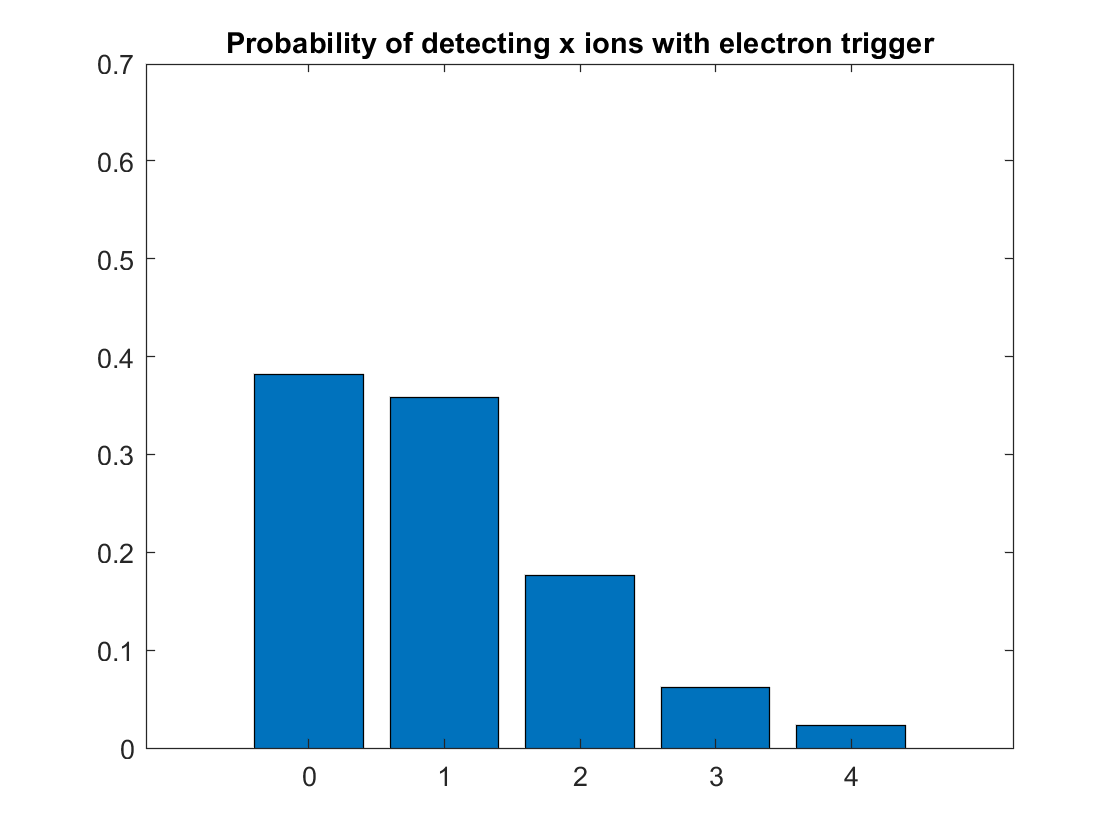

x = 0:1:4;
bar(x ,y1); title('Probability of detecting x ions with electron trigger')
ylim([0.000 0.700])

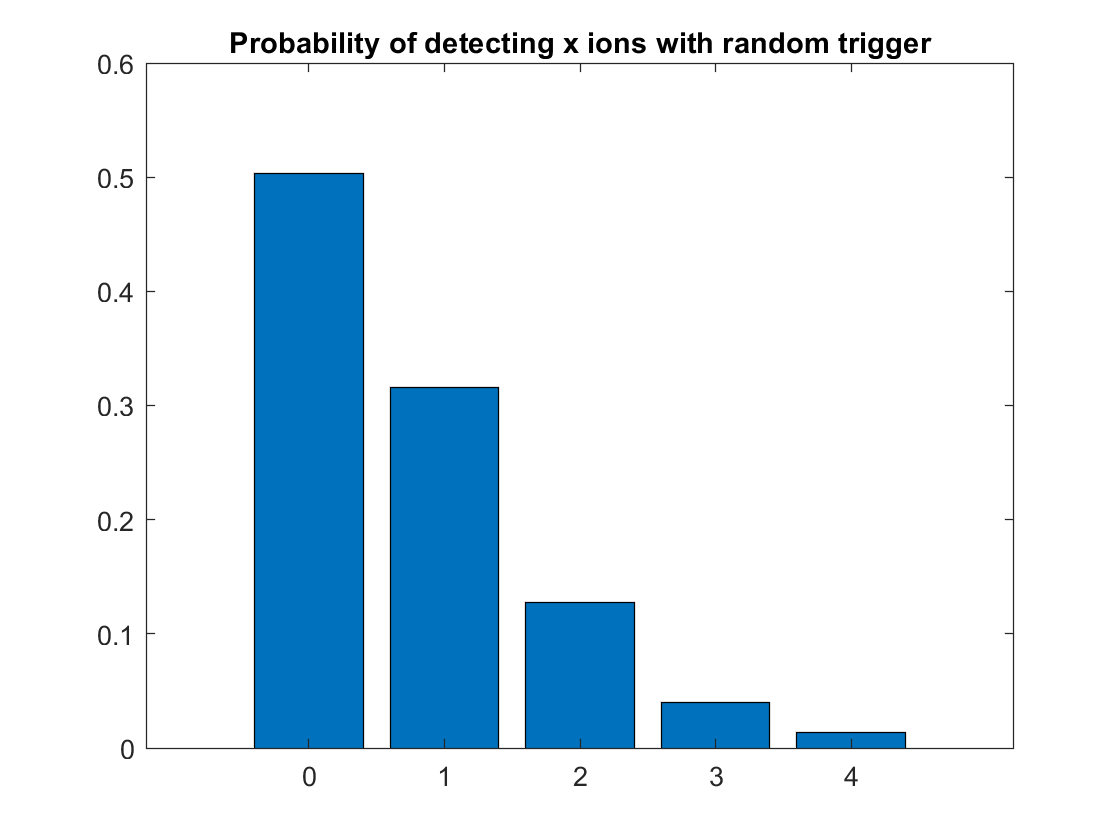

figure
bar(x ,y2); title('Probability of detecting x ions with random trigger')